# Data Visualization Script

## Inital variables

network = 'segnet';
N = 2;
maxepoch = '160';
vis = 0;


if(strcmp(network,'segnet'))
    lr = [0.0001 0.001 0.003];
    bsz = [4 8 12];
else
    lr = [0.0001 0.0005 0.001]
    bsz = [2 8 12];
end

### Folder construction


if(N == 2)
    folder = [network '2_result'];
elseif(N == 4)
    folder = [network '4_result'];
end

file_name = [folder '\compiled_results.mat']

file_name = 'segnet2_result\compiled_results.mat'

Load the data

load(file_name);

dd

BS = [bsz';bsz';bsz'];
LR = [lr';lr';lr'];
for index = 4:5
    temp = [0:160/size(TrainingAccuracy{index},2):160];
    X = temp(2:end);
Y = movmean(TrainingLoss{index},250);
plot(X,log(Y),'k');
hold on
end

## Image Level parameters

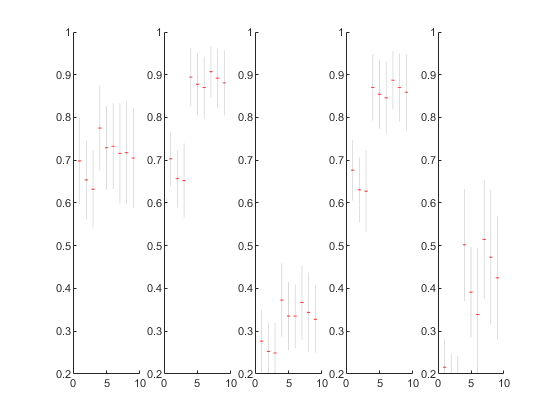

subplot(151);
target = MeanAccuracy;
my_boxplot(target,folder);
subplot(152);
target = GlobalAccuracy;
my_boxplot(target,folder);

subplot(153);
target = MeanIoU;
my_boxplot(target,folder);

subplot(154);
target = WeightedIoU;
my_boxplot(target,folder);

subplot(155);
target = MeanBFScore;
my_boxplot(target,folder);